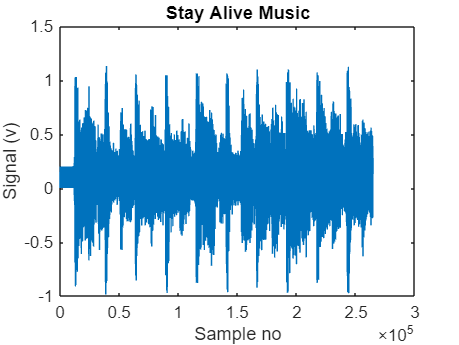

clear all
[sig, fs] = audioread('bgs.wav');
x = sig + 0.2*rand(size(sig));

figure(1);
clf;
plot(x);
xlabel('Sample no');
ylabel('Signal (v)');
title('Stay Alive Music');


N = size(x);

for i=4:N
    y(i) = (x(i)+(x(i-1)+x(i-2)+x(i-3)))/4;
end


y(1)=x(1)/4;
y(2)= (x(2))+(x(1))/4;
y(3)= (x(3)+x(2))+(x(1))/4;

sound(x,fs)
disp('Playing the original -grass return when finished')

Playing the original -grass return when finished


pause;
sound(y,fs)
disp('Playing the filter music')

Playing the filter music


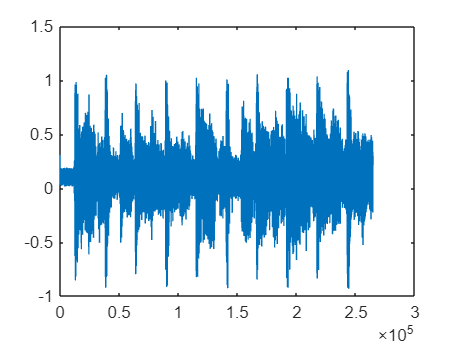

figure;
plot(y)